clear

p = num_agents x 2 matrix of current agent positions

v = num_agents x 2 matrix of current agent velocities

p_1, p_2, …, p_num_agents = 2 x time matrices hold the historic positions, assigned using a for loop

v_1, v_2, …, v_num_agents =  2 x time matrices hold the historic velocities, assigned using a for loop

p_leader_current = 1x2 vector of the current leader position

p_leader = 2 x time vector of historic leader positions

v_leader_current = 1x2 vector of the current leader velocity

v_leader = 2 x time vector of historic leader velocities

num_agents = 2;
p = zeros(num_agents, 2);
v = zeros(num_agents, 2);
p_leader_current = [-4, 0];
v_leader_current = [-4, 0];
num_steps = 75;

% x_pos = [ ...
%     0.000, 0.256, 0.435, 0.424, 0.232, ...
%    -0.067, -0.309, -0.288, -0.073, 0.203, ...
%     0.503, 0.770, 0.892, 0.874, 0.656, ...
%     0.357, 0.094, 0.052, 0.212, 0.511 ];
% 
% y_pos = [ ...
%     0.000, 0.143, 0.368, 0.668, 0.898, ...
%     0.937, 0.758, 0.459, 0.251, 0.145, ...
%     0.125, 0.262, 0.537, 0.836, 1.037, ...
%     1.030, 0.879, 0.582, 0.328, 0.278 ];
% 
% x_vel = [ ...
%     0.256, 0.179, -0.011, -0.192, -0.299, ...
%    -0.242, 0.021, 0.215, 0.276, 0.300, ...
%     0.267, 0.122, -0.018, -0.218, -0.299, ...
%    -0.263, -0.042, 0.160, 0.299, 0.298 ];
% 
% y_vel = [ ...
%     0.143, 0.225, 0.300, 0.230, 0.039, ...
%    -0.179, -0.299, -0.208, -0.106, -0.020, ...
%     0.137, 0.275, 0.299, 0.201, -0.007, ...
%    -0.151, -0.297, -0.254, -0.050, 0.058 ];

x_pos_1 = linspace(0, 2.5, num_steps/3)

x_pos_1 =          0    0.1042    0.2083    0.3125    0.4167    0.5208    0.6250    0.7292    0.8333    0.9375    1.0417    1.1458    1.2500    1.3542    1.4583    1.5625    1.6667    1.7708    1.8750    1.9792    2.0833    2.1875    2.2917    2.3958    2.5000


x_pos_2 = linspace(2.5, -2.5, num_steps/3 * 2)

x_pos_2 =     2.5000    2.3980    2.2959    2.1939    2.0918    1.9898    1.8878    1.7857    1.6837    1.5816    1.4796    1.3776    1.2755    1.1735    1.0714    0.9694    0.8673    0.7653    0.6633    0.5612    0.4592    0.3571    0.2551    0.1531    0.0510   -0.0510   -0.1531   -0.2551   -0.3571   -0.4592   -0.5612   -0.6633   -0.7653   -0.8673   -0.9694   -1.0714   -1.1735   -1.2755   -1.3776   -1.4796   -1.5816   -1.6837   -1.7857   -1.8878   -1.9898   -2.0918   -2.1939   -2.2959   -2.3980   -2.5000



x_pos(1:num_steps/3) = x_pos_1

x_pos =          0    0.1042    0.2083    0.3125    0.4167    0.5208    0.6250    0.7292    0.8333    0.9375    1.0417    1.1458    1.2500    1.3542    1.4583    1.5625    1.6667    1.7708    1.8750    1.9792    2.0833    2.1875    2.2917    2.3958    2.5000


x_pos(((num_steps)/3 +1):num_steps) = x_pos_2

x_pos =          0    0.1042    0.2083    0.3125    0.4167    0.5208    0.6250    0.7292    0.8333    0.9375    1.0417    1.1458    1.2500    1.3542    1.4583    1.5625    1.6667    1.7708    1.8750    1.9792    2.0833    2.1875    2.2917    2.3958    2.5000    2.5000    2.3980    2.2959    2.1939    2.0918    1.9898    1.8878    1.7857    1.6837    1.5816    1.4796    1.3776    1.2755    1.1735    1.0714    0.9694    0.8673    0.7653    0.6633    0.5612    0.4592    0.3571    0.2551    0.1531    0.0510


y_pos = linspace(0, 0, num_steps)

y_pos =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



x_vel = ones(75, 1) * 0.1

x_vel =     0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000


y_vel = zeros(75, 1)

y_vel =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i = 1:num_agents
    eval(sprintf('p_%d = [0; 0];', i));
    eval(sprintf('v_%d = [0; 0];', i));
end

p_1 = [-5; -1];
p_2 = [-5; 1];
%p_3 = [0; -2];
p = [p_1'; p_2'];


collision_count = 0;

for i = 1:num_steps
    N = neighbor_calc(p, num_agents);
    v = agent_velocity(N, p, v, p_leader_current, v_leader_current, num_agents);
    p = position_update(p, v);
    
    for j = 1:num_agents
            eval(sprintf('p_%d(:, end+1) = p(%d, :)'';', j, j)); 
            eval(sprintf('v_%d(:, end+1) = v(%d, :)'';', j, j));
    end

    p_leader_current = [x_pos(i), y_pos(i)];
    v_leader_current = [x_vel(i), y_vel(i)];

    collision_radius = 0.05;
    collisions = check_collisions(p, collision_radius);
    if any(collisions(:))
        collision_count = collision_count + 1;
    end
end

disp(['Total Collision Count: ', num2str(collision_count)]);

Total Collision Count: 0


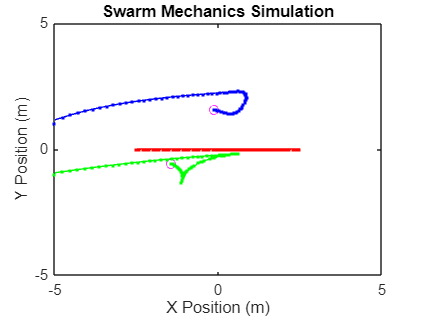


figure;
plot(x_pos, y_pos, 'r.-'); 
hold on;
for i = 1:num_agents
    plot(p(i, 1), p(i, 2), 'mo'); 
    plot(p_1(1, :), p_1(2, :), 'g.-');
    plot(p_2(1, :), p_2(2, :), 'b.-');
    %plot(p_3(1, :), p_3(2, :), 'c.-')
end
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis([-5, 5, -5, 5]);
title('Swarm Mechanics Simulation');

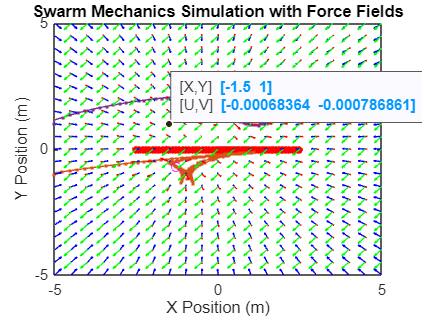

Total Collision Count: 0


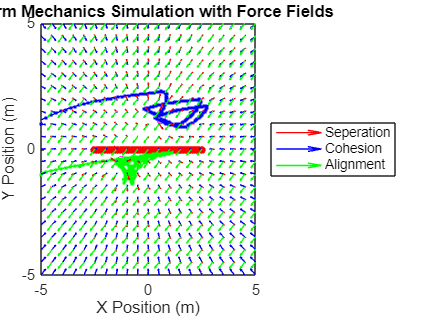

% Parameters for the forces
k_c = 0.05;     % cohesion
k_a = 0.1;      % alignment
k_s = 0.8;      % separation
r_0 = 0.9;      % avoidance range
k_avoid = 0.8;  % repulsion strength

% Grid of hypothetical positions for agent 1
[x_grid, y_grid] = meshgrid(-5:0.5:5, -5:0.5:5);
u_sep = zeros(size(x_grid));  % Separation force (x-component)
v_sep = zeros(size(y_grid));  % Separation force (y-component)

u_coh = zeros(size(x_grid));  % Cohesion force (x-component)
v_coh = zeros(size(y_grid));  % Cohesion force (y-component)

u_align = zeros(size(x_grid));  % Alignment force (x-component)
v_align = zeros(size(y_grid));  % Alignment force (y-component)

% Agent 1's current position and velocity
p1 = p(1, :);  % Position of agent 1
v1 = v(1, :);  % Velocity of agent 1

% Compute forces at each grid point
% Compute forces at each grid point
for ix = 1:size(x_grid, 1)
    for iy = 1:size(y_grid, 2)
        hypothetical_pos = [x_grid(ix, iy), y_grid(ix, iy)];

        % Initialize force components for each grid point
        F_sep = zeros(1, 2);
        F_coh = zeros(1, 2);
        F_align = zeros(1, 2);
        
        % Iterate through all agents to calculate separation, cohesion, and alignment
        for i = 1:num_agents
            % Separation Force (Avoidance)
            r_vec = hypothetical_pos - p(i, :);  % Vector from agent i to hypothetical position
            r = norm(r_vec);  % Distance
            F_sep = F_sep + k_s * (r_vec / r) * log(1 + r_0 / r);
                
            % Cohesion Force (Attraction to neighbors)
            F_coh = F_coh + k_c * (p(i, :) - hypothetical_pos);
                
            % Alignment Force (Align with neighbors)
            F_align = F_align + k_a * (v(i, :) - v1);
        end
        
        % Store the computed forces
        u_sep(ix, iy) = F_sep(1);
        v_sep(ix, iy) = F_sep(2);

        u_coh(ix, iy) = F_coh(1);
        v_coh(ix, iy) = F_coh(2);

        u_align(ix, iy) = F_align(1);
        v_align(ix, iy) = F_align(2);
    end
end

% Main Plot for the Swarm Simulation
figure;

% Plot the positions of the agents
plot(x_pos, y_pos, 'r.-', "MarkerSize", 15); 
hold on;

% Plot the positions and trajectories of the agents
for i = 1:num_agents
    % Ensure each agent's position is plotted, including agent 2 (p_2)
    eval(sprintf('plot(p_%d(1,:), p_%d(2,:), ''.-'');', i, i));  % Plot the trajectory
    plot(p(i, 1), p(i, 2), 'mo'); % Plot the current position
end

% Overlay the force fields as quiver plots
quiver(x_grid, y_grid, u_sep, v_sep, 'r', 'AutoScaleFactor', 0.5);   % Separation
quiver(x_grid, y_grid, u_coh, v_coh, 'b', 'AutoScaleFactor', 0.5);   % Cohesion
quiver(x_grid, y_grid, u_align, v_align, 'g', 'AutoScaleFactor', 0.5); % Alignment

% Labeling and formatting
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis([-5, 5, -5, 5]);
title('Swarm Mechanics Simulation with Force Fields');

hold off;